## This code trains a Neural Style Transfer algorithm and transfers the style of the image to a set of images. Based on Mathworks' example: https://es.mathworks.com/help/deeplearning/ug/train-fast-style-transfer-network.html

## Load Training Data

imageFolder = 'C:\Users\pablosangil\Downloads\Datasets\CheXpert-v1.0-small\resto resnet1\norml';
imds = imageDatastore(imageFolder,'IncludeSubfolders',true);

Training can take a long time to run. If you want to decrease the training time at the cost of accuracy of the resulting network, then select a subset of the image datastore by setting `fraction` to a smaller value.

fraction = 1;
numObservations = numel(imds.Files);
imds = subset(imds,1:floor(numObservations*fraction));

Create augmented image datastore with resized RGB images.

augimds = augmentedImageDatastore([256 256],imds,'ColorPreprocessing',"gray2rgb");

## Style image

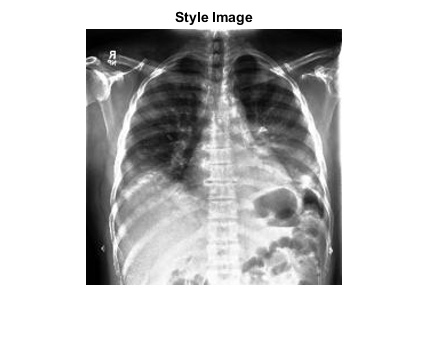


styleImage = imread('C:\Users\pablosangil\Downloads\Datasets\CheXpert-v1.0-small\resto resnet1\pneum\Pneumonia 1213.jpg');
styleImage = imresize(styleImage,[256 256]);

figure
imshow(styleImage)
title("Style Image")

## Define Image Transformer Network

Define the image transformer network. This is an image-to-image network. The network consists of 3 parts:

- The first part of the network takes as input an RGB image of size [256x256x3] and downsamples it to a feature map of size [64x64x128].

- The second part of the network consists of five identical residual blocks defined in the supporting function `residualBlock. `

- The third and final part of the network upsamples the feature map to the original size of the image and returns the transformed image. This last part uses the `upsampleLayer`, which is a custom layer attached to this example as a supporting file.

layers = [
    
    % First part.
    imageInputLayer([256 256 3], 'Name', 'input', 'Normalization','none')
    
    convolution2dLayer([9 9], 32, 'Padding','same','Name', 'conv1')
    groupNormalizationLayer('channel-wise','Name','norm1')
    reluLayer('Name', 'relu1')
    
    convolution2dLayer([3 3], 64, 'Stride', 2,'Padding','same','Name', 'conv2')
    groupNormalizationLayer('channel-wise' ,'Name','norm2')
    reluLayer('Name', 'relu2')
    
    convolution2dLayer([3 3], 128, 'Stride', 2, 'Padding','same','Name', 'conv3')
    groupNormalizationLayer('channel-wise' ,'Name','norm3')
    reluLayer('Name', 'relu3')
    
    % Second part. 
    residualBlock("1")
    residualBlock("2")
    residualBlock("3")
    residualBlock("4")
    residualBlock("5")
    
    % Third part.
    upsampleLayer('up1')
    convolution2dLayer([3 3], 64, 'Stride', 1, 'Padding','same','Name', 'upconv1')
    groupNormalizationLayer('channel-wise' ,'Name','norm6')
    reluLayer('Name', 'relu5')
    
    upsampleLayer('up2')
    convolution2dLayer([3 3], 32, 'Stride', 1, 'Padding','same','Name', 'upconv2')
    groupNormalizationLayer('channel-wise' ,'Name','norm7')
    reluLayer('Name', 'relu6')
    
    convolution2dLayer(9,3,'Padding','same','Name','conv_out')];

lgraph = layerGraph(layers);

Add missing connections in residual blocks.

lgraph = connectLayers(lgraph,"relu3","add1/in2");
lgraph = connectLayers(lgraph,"add1","add2/in2");
lgraph = connectLayers(lgraph,"add2","add3/in2");
lgraph = connectLayers(lgraph,"add3","add4/in2");
lgraph = connectLayers(lgraph,"add4","add5/in2");

Visualize the image transformer network in a plot.

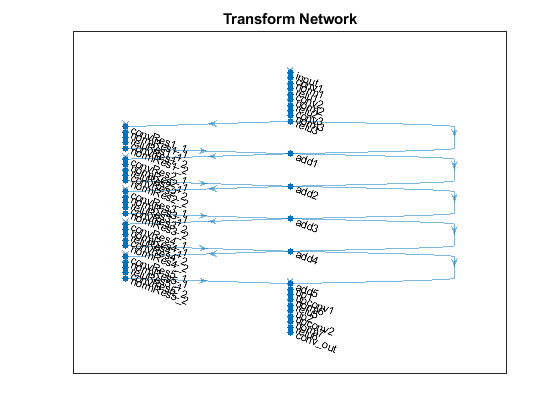

figure
plot(lgraph)
title("Transform Network")

Create a `dlnetwork` object from the layer graph.

dlnetTransform = dlnetwork(lgraph);

## Style Loss Network

A pretrained VGG-16 is used to extract the loss. Only the first 24 layers are needed.

netLoss = vgg16;
lossLayers = netLoss.Layers(1:24);
lgraph = layerGraph(lossLayers);
dlnetLoss = dlnetwork(lgraph);

## Specify Training Options

numEpochs = 2;
miniBatchSize = 4;
augimds.MiniBatchSize = miniBatchSize;

learnRate = 0.001;
gradientDecayFactor = 0.9;
squaredGradientDecayFactor = 0.999;

executionEnvironment = "auto";

Specify the weight given to the style loss and the one given to the content loss in the calculation of the total loss.

weightContent = 1e-4;
weightStyle = 3e-8; 

Plot frequency of the training progress. 

plotFrequency = 10;

## Train Model

In order to be able to compute the loss during training, calculate the Gram matrices for the style image.

Convert the style image to `dlarray`.

dlS = dlarray(single(styleImage),'SSC');

In order to calculate the Gram matrix, feed the style image to the VGG-16 network and extract the activations at four different layers.

[dlSActivations1,dlSActivations2,dlSActivations3,dlSActivations4] = forward(dlnetLoss,dlS, ...
    'Outputs',["relu1_2" "relu2_2" "relu3_3" "relu4_3"]);

Calculate the Gram matrix for each set of activations using the supporting function `createGramMatrix`.

dlSGram{1} = createGramMatrix(dlSActivations1);
dlSGram{2} = createGramMatrix(dlSActivations2);
dlSGram{3} = createGramMatrix(dlSActivations3);
dlSGram{4} = createGramMatrix(dlSActivations4);

Initialize the training plots.

[ax1,ax2,lineLossContent,lineLossStyle,lineLossTotal]=initializeStyleTransferPlots();

Initialize the average gradient and average squared gradient hyperparameters for the ADAM optimizer.

averageGrad = [];
averageSqGrad = [];

Calculate total number of training iterations.

numIterations = floor(augimds.NumObservations*numEpochs/miniBatchSize);

Initialize iteration number and timer before training.

iteration = 0;
start = tic;

Train the model. This could take a long time to run.

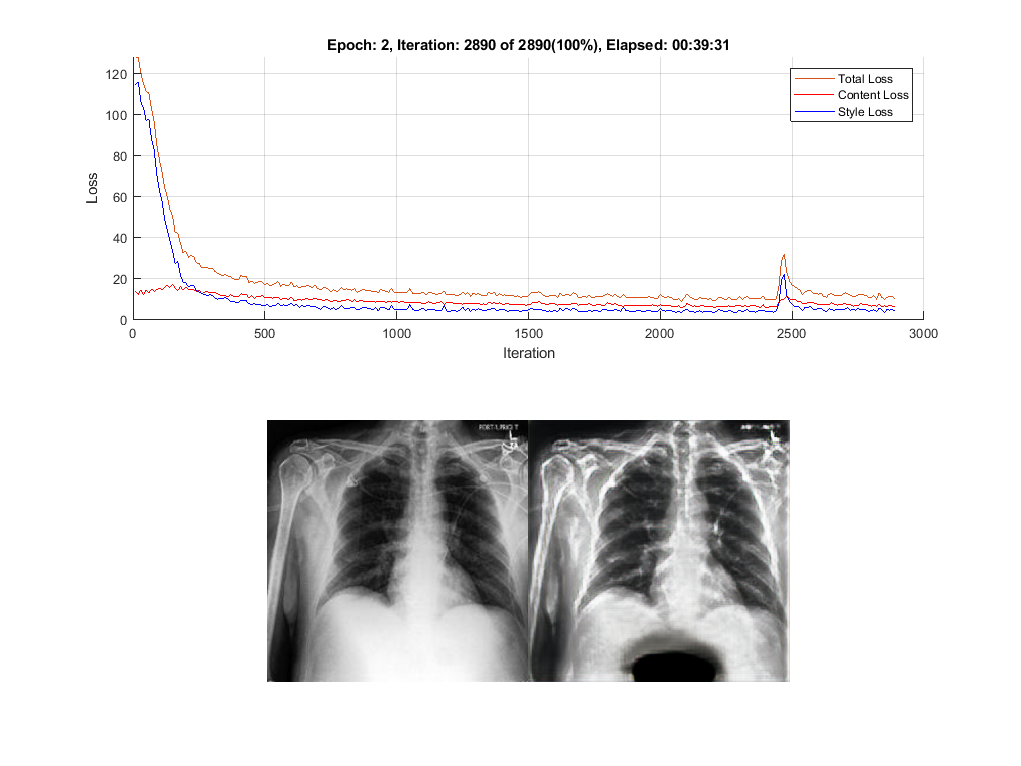

% Loop over epochs.
for i = 1:numEpochs
    
    % Reset and shuffle datastore.
    reset(augimds);
    augimds = shuffle(augimds);
    
    % Loop over mini-batches.
    while hasdata(augimds)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        data = read(augimds);
        
        % Ignore last partial mini-batch of epoch.
        if size(data,1) < miniBatchSize
            continue
        end
        
        % Extract the images from data store into a cell array.
        images = data{:,1};
        
        % Concatenate the images along the 4th dimension.
        X = cat(4,images{:});
        X = single(X);
        
        % Convert mini-batch of data to dlarray and specify the dimension labels
        % 'SSCB' (spatial, spatial, channel, batch).
        dlX = dlarray(X, 'SSCB');
        
        % If training on a GPU, then convert data to gpuArray.
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlX = gpuArray(dlX);
        end
        
        % Evaluate the model gradients and the network state using
        % dlfeval and the modelGradients function listed at the end of the
        % example.
        [gradients,state,dlY,loss,lossContent,lossStyle] = dlfeval(@modelGradients, ...
            dlnetLoss,dlnetTransform,dlX,dlSGram,weightContent,weightStyle);
        
        dlnetTransform.State = state;
        
        % Update the network parameters.
        [dlnetTransform,averageGrad,averageSqGrad] = ...
            adamupdate(dlnetTransform,gradients,averageGrad,averageSqGrad,iteration,...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
              
        
        % Every plotFequency iterations, plot the training progress.
        if mod(iteration,plotFrequency) == 0
            addpoints(lineLossTotal,iteration,double(gather(extractdata(loss))))
            addpoints(lineLossContent,iteration,double(gather(extractdata(lossContent))))
            addpoints(lineLossStyle,iteration,double(gather(extractdata(lossStyle))))
            
            % Use the first image of the mini-batch as a validation image.
            dlV = dlX(:,:,:,1);
            % Use the transformed validation image computed previously.
            dlVY = dlY(:,:,:,1);
            
            % To use the function imshow, convert to uint8.
            validationImage = uint8(gather(extractdata(dlV)));
            transformedValidationImage = uint8(gather(extractdata(dlVY)));
            
            % Plot the input image and the output image and increase size
            imshow(imtile({validationImage,transformedValidationImage}),'Parent',ax2);
        end
        
        % Display time elapsed since start of training and training completion percentage.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        completionPercentage = round(iteration/numIterations*100,2);
        title(ax1,"Epoch: " + i + ", Iteration: " + iteration +" of "+ numIterations + "(" + completionPercentage + "%)" +", Elapsed: " + string(D))
        drawnow
        
    end
end

## Stylize an Image

Once training has finished, you can use the image transformer on any image of your choice.

Load the image you would like to transform.

imFilename = 'C:\Users\pablosangil\Downloads\Datasets\Covid 19 Radiography Database\NORMAL\NORMAL (8).png';
im = imread(imFilename);
im=ind2rgb(im,colormap(gray));

Resize the input image to the input dimensions of the image transformer.

im = imresize(im,[256,256]);

Convert it to `dlarray.`

dlX = dlarray(single(im),'SSCB');

To use the GPU convert to `gpuArray` if one is available.

if canUseGPU
    dlX = gpuArray(dlX);
end

To apply the style to the image, forward pass it to the image transformer using the function `predict.`

dlY = predict(dlnetTransform,dlX);
save('my_train_fast_style_covid_2','dlnetTransform')

Rescale the image into the range [0 255]. First, use the function `tanh` to rescale `dlY` to the range [-1 1]. Then, shift and scale the output to rescale into the [0 255] range.

Y = 255*(tanh(dlY)+1)/2;

Prepare `Y` for plotting. Use the function `extraxtdata` to extract the data from `dlarray.`Use the function gather to transfer Y from the GPU to the local workspace. 

Y = uint8(gather(extractdata(Y)));

Show the input image (left) next to the stylized image (right).

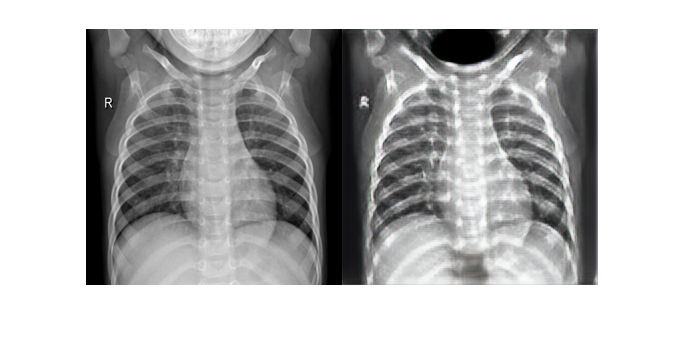

figure
m = imtile({im,Y});
imshow(m)

## Model Gradients Function

The function `modelGradients` takes as input the loss network `dlnetLoss`, the image transformer network `dlnetTransform`, a mini-batch of input images `dlX`, an array containing the Gram matrices of the style image `dlSGram`, the weight associated with the content loss `contentWeight` and the weight associated with the style loss `styleWeight`. It returns the `gradients` of the loss with respect to the learnable parameters of the image transformer, the state of the image transformer network, the transformed images `dlY`, the total loss `loss`, the loss associated with the content `lossContent` and the loss associated with the style `lossStyle.`

function [gradients,state,dlY,loss,lossContent,lossStyle] = ...
    modelGradients(dlnetLoss,dlnetTransform,dlX,dlSGram,contentWeight,styleWeight)

[dlY,state] = forward(dlnetTransform,dlX);

dlY = 255*(tanh(dlY)+1)/2;

[loss,lossContent,lossStyle] = styleTransferLoss(dlnetLoss,dlY,dlX,dlSGram,contentWeight,styleWeight);

gradients = dlgradient(loss,dlnetTransform.Learnables);

end

## Style Transfer Loss

The function `styleTransferLoss` takes as input the loss network `dlnetLoss`, a mini-batch of input images `dlX,` a mini-batch of transformed images `dlY`, an array containing the Gram matrices of the style image `dlSGram`, the weights associated with the content and style `contentWeight` and `styleWeight,` respectively. It returns the total loss `loss` and the individual components: the content loss `lossContent` and the style loss `lossStyle.`

The content loss is a measure of how much difference in spatial structure there is between the input image `X` and the output images `Y`.

On the other hand, the style loss tells you how much difference in the stylistic appearance there is between the style image `S` and the output image `Y`.

First, the function passes the input images `X`, the transformed images `Y` and the style image `S` to the pretrained network VGG-16. This pretrained network extracts several features from these images. The algorithm then calculates the content loss by using the spatial features of the input image X and of the output image Y. Moreover, it calculates the style loss by using the stylistic features of the output image Y and of the style image S.  Finally, it obtains the total loss by adding the content and style losses.

### Loss 

function [loss,lossContent,lossStyle] = styleTransferLoss(dlnetLoss,dlY,dlX, ...
    dlSGram,weightContent,weightStyle)

% Extract activations.
dlYActivations = cell(1,4);
[dlYActivations{1},dlYActivations{2},dlYActivations{3},dlYActivations{4}] = ...
    forward(dlnetLoss,dlY,'Outputs',["relu1_2" "relu2_2" "relu3_3" "relu4_3"]);

dlXActivations = forward(dlnetLoss,dlX,'Outputs','relu3_3');

% Calculate the mean square error between activations.
lossContent = mean((dlYActivations{3} - dlXActivations).^2,'all');

% Add up the losses for all the four activations.
lossStyle = 0;
for j = 1:4
    G = createGramMatrix(dlYActivations{j});
    lossStyle = lossStyle + sum((G - dlSGram{j}).^2,'all');
end

% Average the loss over the mini-batch.
miniBatchSize = size(dlX,4);
lossStyle = lossStyle/miniBatchSize;

% Apply weights.
lossContent = weightContent * lossContent;
lossStyle = weightStyle * lossStyle;

% Calculate the total loss.
loss = lossContent + lossStyle;

end

## Residual Block

The `residualBlock` function returns an array of six layers. It consists of convolution layers, instance normalization layers, a ReLu layer and an addition layer. Note that `groupNormalizationLayer('channel-wise')` is simply an instance normalization layer.

function layers = residualBlock(name)

layers = [    
    convolution2dLayer([3 3], 128, 'Stride', 1,'Padding','same','Name', "convRes"+name+"_1")
    groupNormalizationLayer('channel-wise','Name',"normRes"+name+"_1")
    reluLayer('Name', "reluRes"+name+"_1")
    convolution2dLayer([3 3], 128, 'Stride', 1,'Padding','same', 'Name', "convRes"+name+"_2")
    groupNormalizationLayer('channel-wise','Name',"normRes"+name+"_2")
    additionLayer(2,'Name',"add"+name)];

end

## Gram Matrix

function G = createGramMatrix(activations)

[h,w,numChannels] = size(activations,1:3);

features = reshape(activations,h*w,numChannels,[]);
featuresT = permute(features,[2 1 3]);

G = dlmtimes(featuresT,features) / (h*w*numChannels);

end